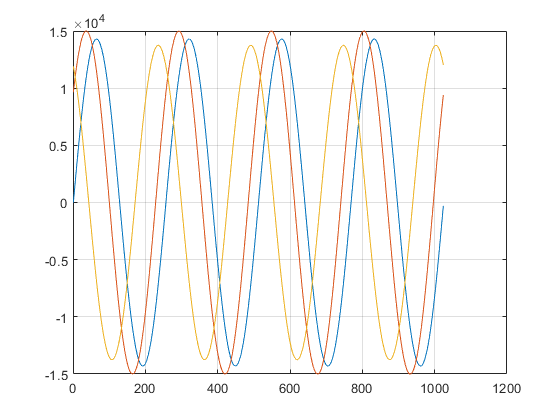

Amp = [14300 15000 13750];
Shift = [32305 32307 15000]*0;
phase = [0 40 120];
f = 50.01;
ts = 1/12800;
t = linspace(0,ts*DSP_LEN-ts,DSP_LEN);

testInput = zeros([DSP_LEN,length(Amp)]);
for n = 1:length(Amp)
    testInput(:,n) = Amp(n)*sin(2*pi*f.*t + phase(n)./180.*pi) + Shift(n);
end

plot(testInput);
grid on;

% testInput =

fftOut = fft(testInput,DSP_LEN);
fftOut(abs(fftOut) < max(abs(fftOut))/10000) = 0;


fftRe = real(fftOut(1:DSP_LEN/2,:));
fftIm = imag(fftOut(1:DSP_LEN/2,:));

fftPhase = atan2(fftRe,fftIm)*180/pi;
maxPhase = [fftPhase(5,1) fftPhase(5,2) fftPhase(5,3)];
maxPhase(1)-maxPhase(2)

ans = 40.0057

maxPhase(2)-maxPhase(3)

ans = 79.9895

maxPhase(3)-maxPhase(1)

ans = -119.9952

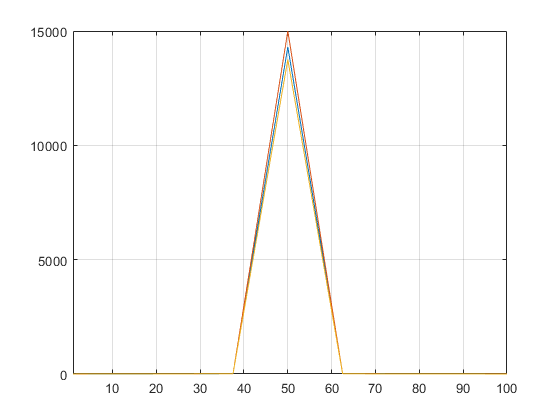



fftAbs = abs(fftOut(1:DSP_LEN/2,:))/DSP_LEN*2;
fftAbs(1,:)=fftAbs(1,:)/2;


f = fs*(0:(DSP_LEN/2)-1)/DSP_LEN;
plot(f,fftAbs)
grid on
xlim([1 100])

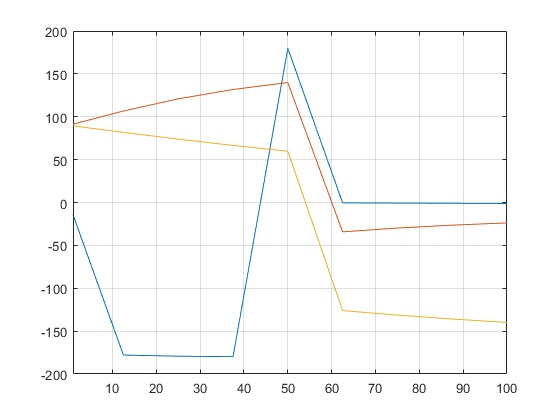


plot(f,fftPhase)
grid on
xlim([1 100])


clear f